**Exercise 1:**

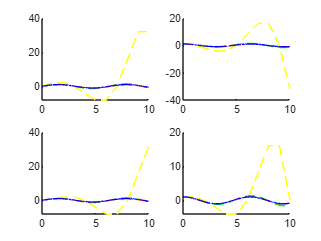

A = [0 -1;1 0];
x_0 = 1;
y_0 = 0;
T = 10;
N = 10;

[x, y] = IEMsolver(A, x_0, y_0, T, N);
[xem, yem] = EMsolver(A, x_0, y_0, T, N);

N = 100;
[x1, y1] = IEMsolver(A, x_0, y_0, T, N);
[xem1, yem1] = EMsolver(A, x_0, y_0, T, N);

N = 1000;
[x2, y2] = IEMsolver(A, x_0, y_0, T, N);
[xem2, yem2] = EMsolver(A, x_0, y_0, T, N);

% IEM Plots
% Y Plots
subplot(2,2,1)
hold on
t = 0:T/10:T;

plot(t, y,"y--")

t = 0:T/100:T;
plot(t, y1,"g--")

t = 0:T/1000:T;
plot(t, y2,"r--")

t = 0:T/10000:T;
plot(t, sin(t),"b-")
hold off

% X Plots
subplot(2,2,2)
hold on
t = 0:T/10:T;
plot(t, x, "y--")

t = 0:T/100:T;
plot(t, x1, "g--")

t = 0:T/1000:T;
plot(t, x2, "r--")

t = 0:T/10000:T;
plot(t,cos(t),"b-")
hold off

% EM Plots
% Y plots
subplot(2,2,3)
hold on
t = 0:T/10:T;

plot(t, yem,"y--")

t = 0:T/100:T;
plot(t, yem1,"g--")

t = 0:T/1000:T;
plot(t, yem2,"r--")

t = 0:T/10000:T;
plot(t, sin(t),"b-")
hold off

subplot(2,2,4)
hold on
t = 0:T/10:T;
plot(t, xem, "y--")

t = 0:T/100:T;
plot(t, xem1, "g--")

t = 0:T/1000:T;
plot(t, xem2, "r--")

t = 0:T/10000:T;
plot(t,cos(t),"b-")
hold off

**Exercise 2:**

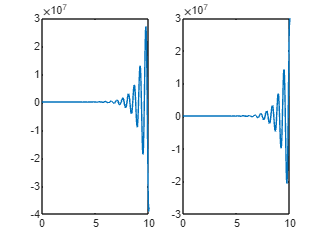

k1 = 4.66;
k2 = 4.66;
m1 = 0.0917;
m2 = 0.0765;
A = [0 1 0 0; (-k1-k2)/m1 0 k2/m1 0; 0 0 0 1; k2/m2 0 -k2/m2 0];
x1_0 = 100;
x2_0 = 50;
y1_0 = 0;
y2_0 = 0;
T = 10;
N = 500;
[x1, y1, x2, y2] = CoupledIEMsolver(A, x1_0, y1_0, x2_0, y2_0, T, N);
t = 0:T/N:T;

figure
subplot(1,2,1)
plot(t, x1)
subplot(1,2,2)
plot(t, x2)


%t = 0:T/N:T;
%subplot(1,2,1)
%plot(t, x11)
%subplot(1,2,2)
%plot(t, x21)

**Functions:**

function [x,y] = EMsolver(A,x_0,y_0,T,N)
dt = T/N;
t = 0:dt:T;
SOL = NaN(2,length(t));
SOL(1,1) = x_0;
SOL(2,1) = y_0;
for k = 2:length(t)
SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
end
x = SOL(1,:);
y = SOL(2,:);
end

function [x,y] = IEMsolver(A, x_0, y_0, T, N)
dt = T/N;
t = 0:dt:T;
SOL = NaN(2,length(t));
SOLem = NaN(2,length(t));
SOL(1,1) = x_0;
SOL(2,1) = y_0;
for k = 2:length(t)
[xem, yem] = EMsolver(A,x_0,y_0,T,N);
SOLem(1,:) = xem;
SOLem(2,:) = yem;
SOL(:,k) =  SOLem(:,k) + (dt/2)*(A*SOL(:, k-1) + A*SOLem(:,k));
end
x = SOL(1,:);
y = SOL(2,:);
end

function [x1, y1, x2, y2] = CoupledEMsolver(A, x1_0, y1_0, x2_0, y2_0, T, N)
dt = T/N;
t = 0:dt:T;
SOL = NaN(2,length(t));
SOL(1,1) = x1_0;
SOL(2,1) = y1_0;
SOL(3,1) = x2_0;
SOL(4,1) = y2_0;

for k = 2:length(t)
SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
end
x1 = SOL(1,:);
y1 = SOL(2,:);
x2 = SOL(3,:);
y2 = SOL(4,:);
end

function [x1, y1, x2, y2] = CoupledIEMsolver(A, x1_0, y1_0, x2_0, y2_0, T, N)
dt = T/N;
t = 0:dt:T;
SOLem = NaN(2,length(t));
SOL = NaN(2,length(t));
SOL(1,1) = x1_0;
SOL(2,1) = y1_0;
SOL(3,1) = x2_0;
SOL(4,1) = y2_0;

for k = 2:length(t)
[x1em, y1em, x2em, y2em] = CoupledEMsolver(A,x1_0,y1_0,x2_0,y2_0,T,N);
SOLem(1,:) = x1em;
SOLem(2,:) = y1em;
SOLem(3,:) = x2em;
SOLem(4,:) = y2em;

SOL(:,k) =  SOLem(:,k) + (dt/2)*(A*SOL(:, k-1) + A*SOLem(:,k));
end

x1 = SOL(1,:);
y1 = SOL(2,:);
x2 = SOL(3,:);
y2 = SOL(4,:);
end
